## Plot the workspace of the robot

step = 360/20;
nb_points = round(360/step);
%disp(nb_points);
%disp(nb_points^3);
xwork = zeros(nb_points^2) ; % reserving space for the variables, because
ywork = zeros(nb_points^2) ; % otherwise they would be created later within a loop.
zwork = zeros(nb_points^2);
i=1;
q5 = 0;
max = 0;

for q1 = 0:step:360
    for q2 = 0:step:180
        for q3 = -65:step:115
            for q4 = -180:step:0
                L_q = [q1 q2 q3 q4 q5];
                pos = forward_kinematics(L_q);
                if (pos(1)^2+pos(2)^2+pos(3)^2)^0.5 >0
                    max = (pos(1)^2+pos(2)^2+pos(3)^2)^0.5;
                    xwork(i) = pos(1);
                    ywork(i) = pos(2);
                    zwork(i) = pos(3);
                    i = i+1;
                end
            end
        end
    end
end    


figure (3)
set(3,'position')
plot3(0,0,0,'o')
hold on
[xp, yp] = meshgrid(-0.5:1:0.5); % Generate x and y data
zp = zeros(size(xp, 1)); % Generate z data
surf(xp, yp, zp) % Plot the surface
plot3(xwork,ywork,zwork,'rx')  % plot the  workspace of the robot
axis equal

title('3D Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
hold off


plot(xwork,ywork,'rx')
title('XY Workspace') ; xlabel('x (m)') ; ylabel('y (m)');
axis equal



plot(xwork,zwork,'rx')
title('XZ Workspace') ; xlabel('x (m)') ; ylabel('z (m)');
axis equal


plot(ywork,zwork,'rx')
title('YZ Workspace') ; xlabel('y (m)') ; ylabel('z (m)');
axis equal



## Inverse Kinematics

theta_input = [0 10 10 50 0];

list1 = plot_links(theta_input);
end_pose = forward_kinematics(theta_input)
theta_recalcule=inv_kin3(end_pose(1), end_pose(2) ,end_pose(3),end_pose(4),end_pose(5))
end_pose2 = forward_kinematics(theta_recalcule)
list2 = plot_links(theta_recalcule)


%go to position

end_pose = [ 0.2  0.2  0  0 0;
             0.2 -0.2  0  0 0;
             0.2 -0.2  0.2  0 0;
             0.2  0  0.3  0 0;
             0.2  0.2  0.2  0 0]

         
path = 

hold on
set(gca,'XLim',[0 0.3],'YLim',[-0.3 0.3],'ZLim',[0 0.4])
set(gcf,'Visible','on')
title('3D Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
view(147,25)
grid on
pause(1)
for i = 1:length(end_pose)
    theta_recalcule=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5))
    end_pose2 = forward_kinematics(theta_recalcule)
    list2 = plot_links(theta_recalcule)
    drawnow
    pause(1)
    
end


%FREE MOTION

end_pose = [ 0.2  0.2  0  0 0;
             0.2 -0.2  0  0 0;
             0.2 -0.2  0.2  0 0;
             0.2  0  0.3  0 0;
             0.2  0.2  0.2  0 0;
             0.2  0.2  0  0 0]

end_pose =     0.2000    0.2000         0         0         0
    0.2000   -0.2000         0         0         0
    0.2000   -0.2000    0.2000         0         0
    0.2000         0    0.3000         0         0
    0.2000    0.2000    0.2000         0         0
    0.2000    0.2000         0         0         0








nb_of_points = 10

nb_of_points = 10

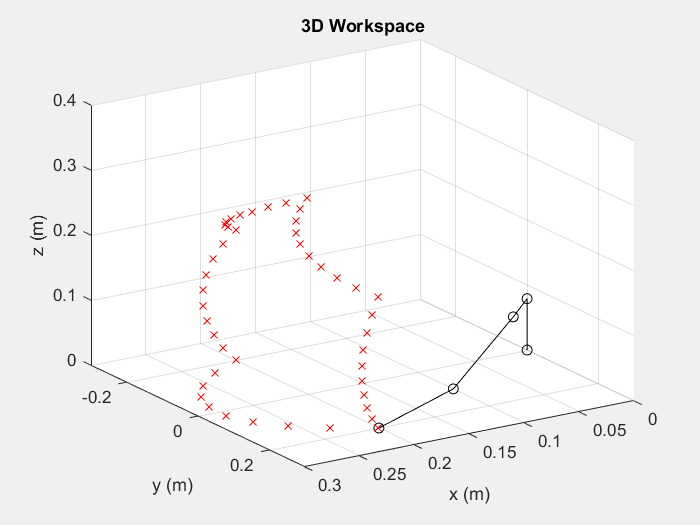

list_pos =          0         0    0.0186    0.0996    0.2000    0.2000
         0         0    0.0186    0.0996    0.2000    0.2000
         0    0.0790    0.0622   -0.0000   -0.0000   -0.0000


drawing =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0.0186 0.0996 0.2000 0.2000]
              YData: [0 0 0.0186 0.0996 0.2000 0.2000]
              ZData: [0 0.0790 0.0622 -1.3878e-17 -1.3878e-17 -1.3878e-17]

  Show all properties



for i = 1:length(end_pose)-1
    
    thetas_i1=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5));
    thetas_i2=inv_kin3(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5));
    
    thetas_table = zeros(5,nb_of_points);
    
    for index_theta = 1:length(thetas_i1)
        spaced_thetas = linspace(thetas_i1(index_theta),thetas_i2(index_theta),nb_of_points) ;  % creates 500 points between 1 and 10 
        for index_point = 1:nb_of_points
            thetas_table(index_theta,index_point) = spaced_thetas(index_point);
        end 
    end
    
    for index_point = 1:nb_of_points
        theta_now = [thetas_table(1,index_point), thetas_table(2,index_point), thetas_table(3,index_point), thetas_table(4,index_point), thetas_table(5,index_point)];
        [list_pos,drawing] = plot_links(theta_now);
        
        drawnow
        pause(0.002)
        delete(drawing);
        
    end
    
end

[list_pos,drawing] = plot_links(theta_now)

%STRAIGHT LINE


end_pose = [ 0.2  0.2  0  0 0;
             0.2 -0.2  0  0 0;
             0.2 -0.2  0.2  0 0;
             0.2  0  0.3  0 0;
             0.2  0.2  0.2  0 0;
             0.2  0.2  0  0 0]

end_pose =     0.2000    0.2000         0         0         0
    0.2000   -0.2000         0         0         0
    0.2000   -0.2000    0.2000         0         0
    0.2000         0    0.3000         0         0
    0.2000    0.2000    0.2000         0         0
    0.2000    0.2000         0         0         0



nb_of_points = 50

nb_of_points = 50


for i = 1:length(end_pose)-1
    
    thetas_i1=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5));
    thetas_i2=inv_kin3(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5));
    
    pos_table = zeros(5,nb_of_points);
    
    disp('hi')
    for index_parameter = 1:5
        spaced_parameter = linspace(end_pose(i,index_parameter),end_pose(i+1,index_parameter),nb_of_points) ;  % creates points
        for index_point = 1:nb_of_points
            pos_table(index_parameter,index_point) = spaced_parameter(index_point);
        end 
        disp(spaced_parameter)
    end
    
    for index_point = 1:nb_of_points
        
        theta_now = inv_kin3(pos_table(1,index_point), pos_table(2,index_point) ,pos_table(3,index_point),pos_table(4,index_point),pos_table(5,index_point));
        [list_pos,drawing] = plot_links(theta_now);
        
        
        drawnow
        pause(0.001)
        delete(drawing);
        
    end
    
end

hi


  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 31 through 40

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 41 through 50

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

    0.2000    0.1918    0.1837    0.1755    0.1673    0.1592    0.1510    0.1429    0.1347    0.1265

  Columns 11 through 20

    0.1184    0.1102    0.1020    0.0939    0.0857    0.0776    0.0694    0.0612    0.0531    0.0449

  Columns 21 through 30

    0.0367    0.0286    0.0204    0.0122    0.0041   -0.0041   -0.0122   -0.0204   -0.02

hi


  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 31 through 40

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 41 through 50

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000

  Columns 11 through 20

   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000

  Columns 21 through 30

   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.2000   -0.20

hi


  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 31 through 40

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 41 through 50

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

   -0.2000   -0.1959   -0.1918   -0.1878   -0.1837   -0.1796   -0.1755   -0.1714   -0.1673   -0.1633

  Columns 11 through 20

   -0.1592   -0.1551   -0.1510   -0.1469   -0.1429   -0.1388   -0.1347   -0.1306   -0.1265   -0.1224

  Columns 21 through 30

   -0.1184   -0.1143   -0.1102   -0.1061   -0.1020   -0.0980   -0.0939   -0.0898   -0.08

hi


  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 31 through 40

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 41 through 50

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

         0    0.0041    0.0082    0.0122    0.0163    0.0204    0.0245    0.0286    0.0327    0.0367

  Columns 11 through 20

    0.0408    0.0449    0.0490    0.0531    0.0571    0.0612    0.0653    0.0694    0.0735    0.0776

  Columns 21 through 30

    0.0816    0.0857    0.0898    0.0939    0.0980    0.1020    0.1061    0.1102    0.11

hi


  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 31 through 40

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 41 through 50

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.20

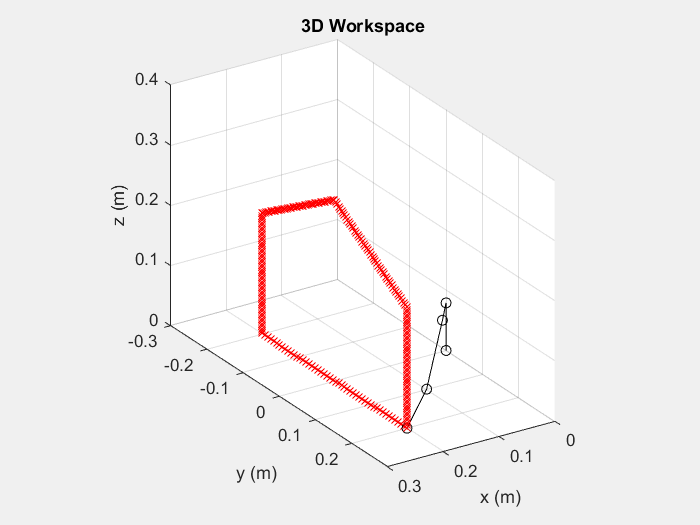

list_pos =          0         0    0.0186    0.0996    0.2000    0.2000
         0         0    0.0186    0.0996    0.2000    0.2000
         0    0.0790    0.0622   -0.0000   -0.0000   -0.0000


drawing =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0.0186 0.0996 0.2000 0.2000]
              YData: [0 0 0.0186 0.0996 0.2000 0.2000]
              ZData: [0 0.0790 0.0622 -1.3878e-17 -1.3878e-17 -1.3878e-17]

  Show all properties



[list_pos,drawing] = plot_links(theta_now)

%SWITH OBSTALCE

end_pose = [ 0.2  0.2  0  0 0;
             0.2 -0.2  0  0 0;
             0.2 -0.2  0.2  0 0;
             0.2  0  0.3  0 0;
             0.2  0.2  0.2  0 0;
             0.2  0.2  0  0 0]

end_pose =     0.2000    0.2000         0         0         0
    0.2000   -0.2000         0         0         0
    0.2000   -0.2000    0.2000         0         0
    0.2000         0    0.3000         0         0
    0.2000    0.2000    0.2000         0         0
    0.2000    0.2000         0         0         0



nb_of_points = 30

nb_of_points = 30


r_cyl = 0.05;

plot_obstacle(r_cyl);

for i = 1:length(end_pose)-1
    
    thetas_i1=inv_kin3(end_pose(i,1), end_pose(i,2) ,end_pose(i,3),end_pose(i,4),end_pose(i,5));
    thetas_i2=inv_kin3(end_pose(i+1,1), end_pose(i+1,2) ,end_pose(i+1,3),end_pose(i+1,4),end_pose(i+1,5));
    
    pos_table = zeros(5,nb_of_points);
    

    for index_parameter = 1:5
        spaced_parameter = linspace(end_pose(i,index_parameter),end_pose(i+1,index_parameter),nb_of_points) ;  % creates points
        for index_point = 1:nb_of_points
            pos_table(index_parameter,index_point) = spaced_parameter(index_point);
        end 
        disp(spaced_parameter)
    end
    
    for index_point = 1:nb_of_points
        dist_to_cylinder = (pos_table(2,index_point)^2 + pos_table(3,index_point)^2)^0.5;
        while dist_to_cylinder < 2*r_cyl
            pos_table(3,index_point) = pos_table(3,index_point) + 0.01 ; 
            
            dist_to_cylinder = (pos_table(2,index_point)^2 + pos_table(3,index_point)^2)^0.5;
        end
        
        theta_now = inv_kin3(pos_table(1,index_point), pos_table(2,index_point) ,pos_table(3,index_point),pos_table(4,index_point),pos_table(5,index_point));
        [list_pos,drawing] = plot_links(theta_now);
        
        
        drawnow
        pause(0.001)
        delete(drawing);
        
    end
    
end

  Columns 1 through 10

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 11 through 20

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 21 through 30

    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000

  Columns 1 through 10

    0.2000    0.1862    0.1724    0.1586    0.1448    0.1310    0.1172    0.1034    0.0897    0.0759

  Columns 11 through 20

    0.0621    0.0483    0.0345    0.0207    0.0069   -0.0069   -0.0207   -0.0345   -0.0483   -0.0621

  Columns 21 through 30

   -0.0759   -0.0897   -0.1034   -0.1172   -0.1310   -0.1448   -0.1586   -0.1724   -0.1862   -0.2000

  Columns 1 through 17

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 18 through 30

     0     0     0     0     0     0     0     0     0     0     0     0     0

  Colum

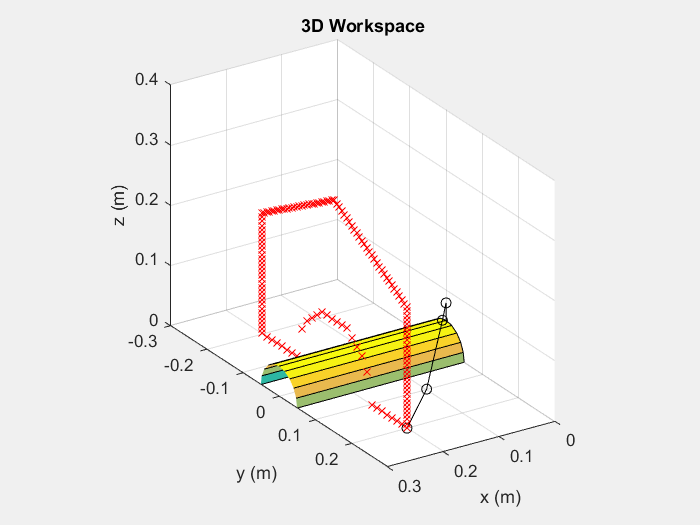

list_pos =          0         0    0.0186    0.0996    0.2000    0.2000
         0         0    0.0186    0.0996    0.2000    0.2000
         0    0.0790    0.0622   -0.0000   -0.0000   -0.0000


drawing =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0 0.0186 0.0996 0.2000 0.2000]
              YData: [0 0 0.0186 0.0996 0.2000 0.2000]
              ZData: [0 0.0790 0.0622 -1.3878e-17 -1.3878e-17 -1.3878e-17]

  Show all properties



[list_pos,drawing] = plot_links(theta_now)